
compute_base_arm(0,0,true);

boatMass = 329.0241

centerOfMass =     0.0000    1.5088    0.0000


volume = 43.2885

rhoTotal = 7.6007

displacementRatio = 0.4750

d = 2.0816

centerOfBuoyancy =    -0.0000    1.4078   -0.0000


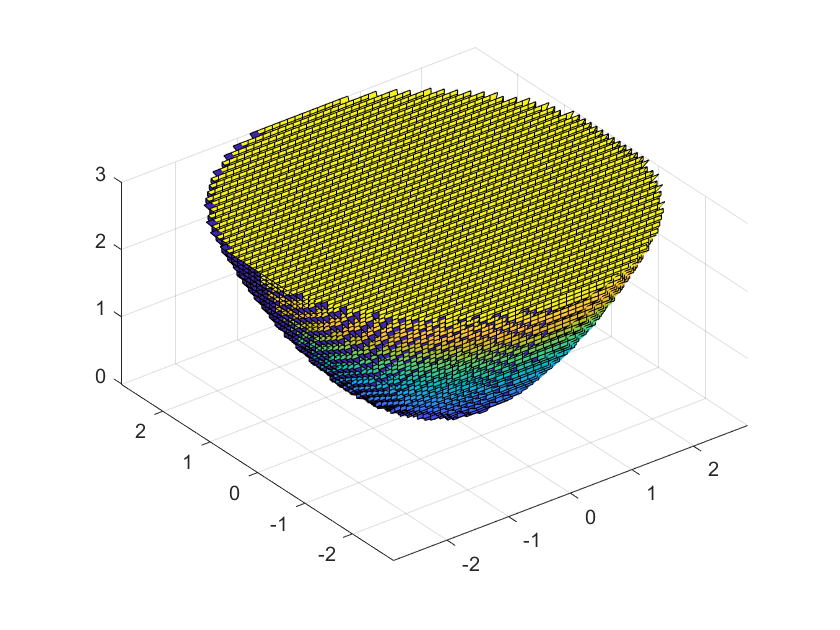


% Moment Arm Curve
pitchVals = linspace(-0, 180, 720);
rollVals = linspace(0, 180, 360);
momentArmPitch = zeros(size(pitchVals, 2), 2);
momentArmRoll = zeros(size(rollVals, 2), 2);
hold on;

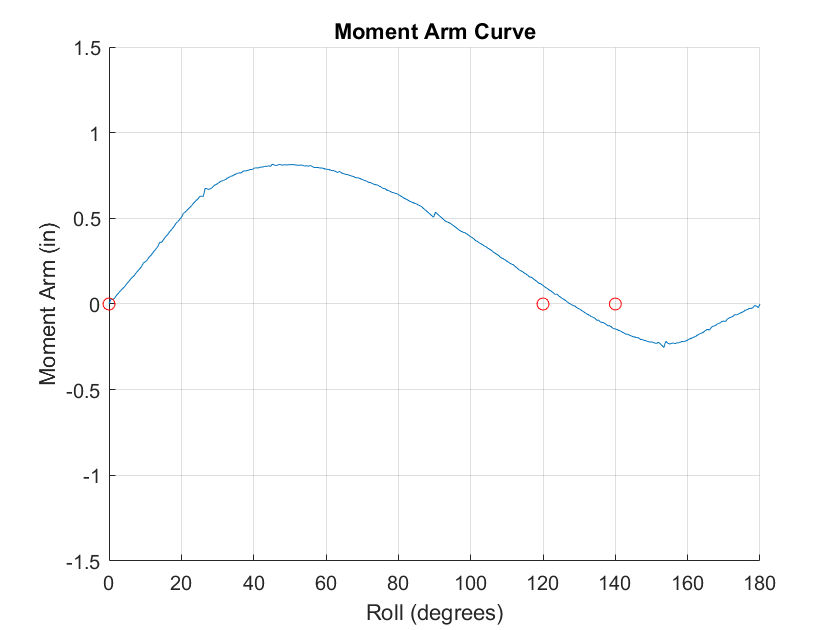


%{
% Varying Pitch
for i = 1:size(momentArmPitch, 1)
    arm = compute_base_arm(pitchVals(i), 0, false);
    momentArmPitch(i,:) = arm';
end

figure(2)
clf
grid on;
hold on;
plot(pitchVals, momentArmPitch(:,1));
plot([0;120;140],[0;0;0], "or");
xlabel("Pitch (degrees)");
ylabel("Moment Arm X-Val");
xlim([-180,180]);
ylim([-0.3,0.3]);
hold off;

figure(3)
clf
grid on;
hold on;
plot(pitchVals, momentArmPitch(:,2));
plot([0;120;140],[0;0;0], "or");
xlabel("Pitch (degrees)");
ylabel("Moment Arm Z-Val");
xlim([-180,180]);
ylim([-0.3,0.3]);
hold off;
%}
% Varying Roll
for i = 1:size(momentArmRoll, 1)
    arm = compute_base_arm(0, rollVals(i), false);
    momentArmRoll(i,:) = arm';
end

figure(4)
clf
grid on;
hold on;
plot(rollVals, momentArmRoll(:,1));
plot([0;120;140],[0;0;0], "or");
xlabel("Roll (degrees)");
ylabel("Moment Arm (in)");
title("Moment Arm Curve");
xlim([0,180]);
ylim([-1.5,1.5]);
hold off;

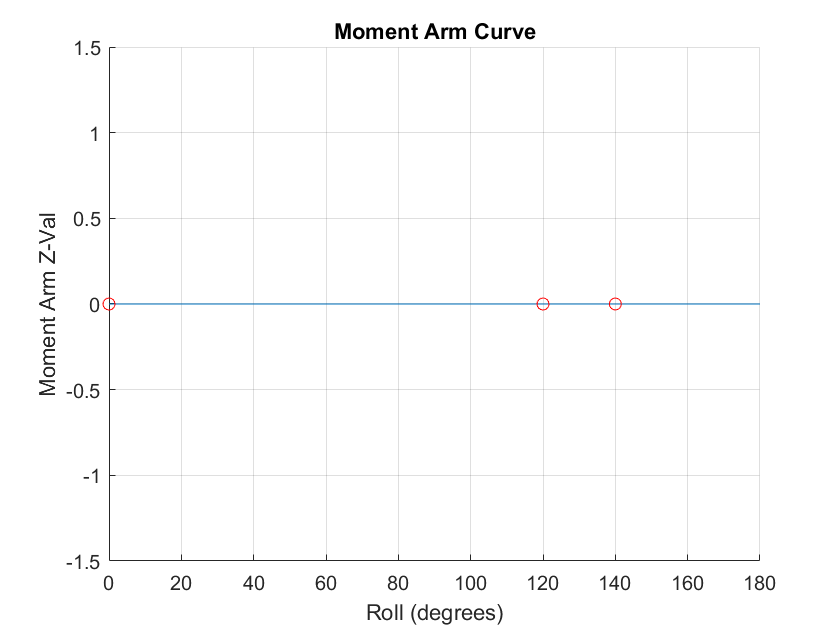


figure(5)
clf
grid on;
hold on;
plot(rollVals, momentArmRoll(:,2));
plot([0;120;140],[0;0;0], "or");
xlabel("Roll (degrees)");
ylabel("Moment Arm Z-Val");
title("Moment Arm Curve");
xlim([0,180]);
ylim([-1.5,1.5]);
hold off;


prevMomentArm = 0;
for index = 1:length(momentArmRoll)
    momentArm = momentArmRoll(index, 1);
    roll = rollVals(index);
    if roll > 0 && momentArm < 0 && prevMomentArm > 0
        avs = rollVals(index)
    end
    prevMomentArm = momentArm;
end

avs = 127.8552

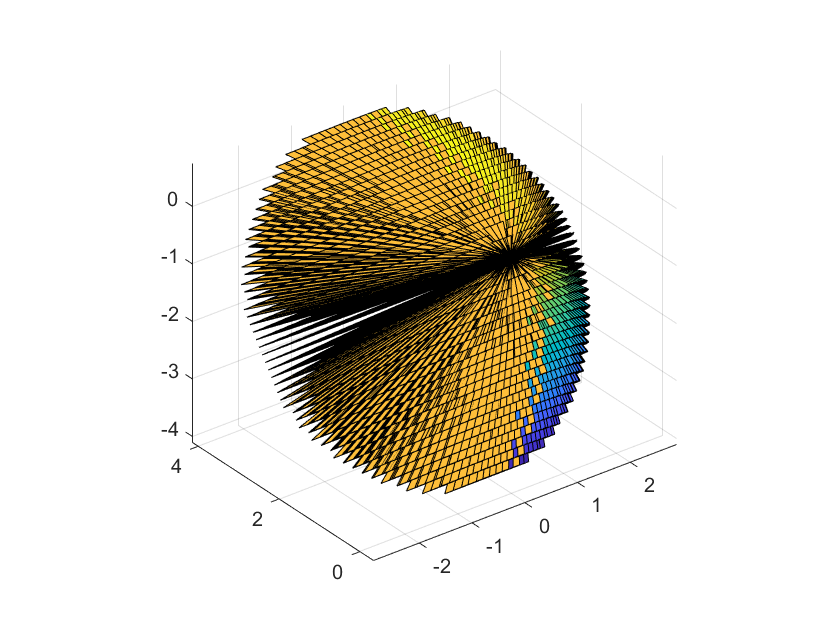

boatMass = 329.0241

centerOfMass =     0.0000   -0.9259    1.1913


volume = 43.2885

rhoTotal = 7.6007

displacementRatio = 0.4750

d = -1.2241

centerOfBuoyancy =    -0.0000   -2.1754    1.1880



compute_base_arm(avs,0,true);

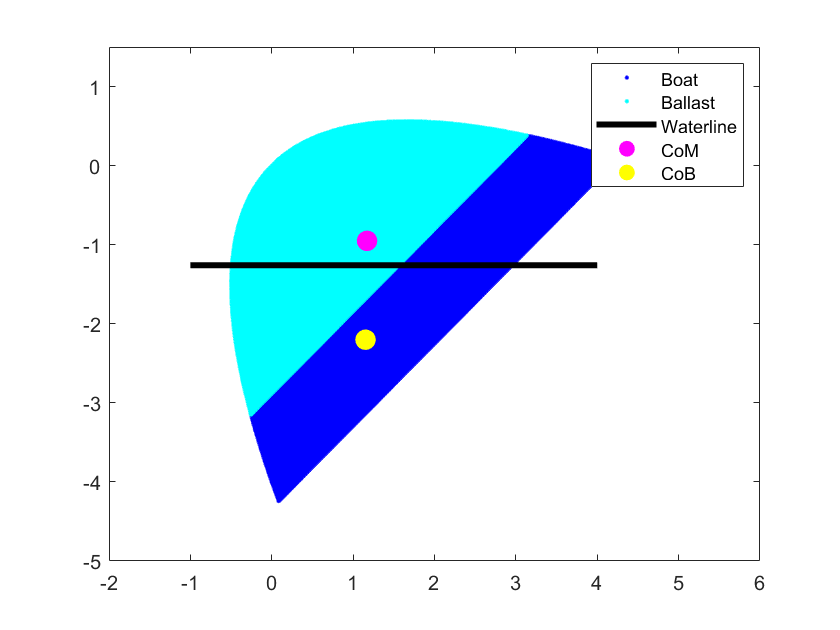



angle = 128;
waterlineY = -1.2592;
com = [1.1710; -0.9514];
cob = [1.1524; -2.2016];

%{
% Unrotate points
rotation = [cosd(0), -sind(0) 0; sind(0), cosd(0) 0; 0, 0, 1]...
    * [1, 0, 0; 0, cosd(-angle), -sind(-angle); 0, sind(-angle), cosd(-angle)];
unrot = inv(rotation);
waterline = unrot * [0; waterlineY; 0];
waterline = waterline(2)
com = unrot * com
cob = unrot * cob
%}

maxX = 3;
maxY = 3;

nPoints = 500;
xVals = linspace(-maxX, maxX, nPoints);
yVals = linspace(0, maxY, nPoints);
[x, y] = meshgrid(xVals, yVals);
points = [x(:), y(:)];
inBoat = maxY * (points(:,1) / maxX) .^ 2 - points(:,2) <= 0;
inBallast = points(:,2) <= 2;

rotation = [cos(-angle), -sin(-angle); sin(-angle), cos(-angle)];
points = (rotation * points')';

figure(1);
clf;
plot(points(inBoat & ~inBallast,1), points(inBoat & ~inBallast,2),'.b');
hold on;
plot(points(inBoat & inBallast,1), points(inBoat & inBallast,2),'.c');
wVals = linspace(-1, 4, 100);
plot(wVals, waterlineY * ones(size(wVals)), '-k', 'LineWidth', 3);
plot(com(1), com(2), '.m', 'MarkerSize', 35);
plot(cob(1), cob(2), '.y', 'MarkerSize', 35);
hold off;
xlim([-2, 6]);
ylim([-5, 1.5]);
legend(["Boat", "Ballast", "Waterline", "CoM", "CoB"]);